clc; clear; close all;

%% Step 1: Load Dataset
disp("1) Loading HandGestures dataset...");

1) Loading HandGestures dataset...


imds = imageDatastore('HandGestures', ...
    'IncludeSubfolders', true, ...
    'LabelSource', 'foldernames');

disp("   Class Distribution:");

   Class Distribution:


disp(countEachLabel(imds));

      Label      Count
    _________    _____

    Fist         1000 
    Heart        1000 
    Okay         1000 
    Peace        1000 
    thumbs_up    1000 



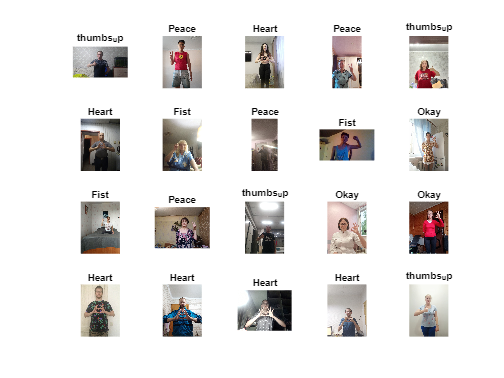


% Display 20 random samples
figure('Name','Sample Images','NumberTitle','off');
perm = randperm(numel(imds.Files), 20);
for i = 1:20
    subplot(4,5,i);
    imshow(readimage(imds,perm(i)));
    title(string(imds.Labels(perm(i))),'FontSize',8);
end


%% Step 2: Split Dataset (80% Train / 20% Val)
[trainImgs, valImgs] = splitEachLabel(imds, 0.8, 'randomized');
disp("2) Split into training & validation sets.");

2) Split into training & validation sets.



%% Step 3: Load Pretrained AlexNet
disp("3) Loading AlexNet...");

3) Loading AlexNet...


net = alexnet;
inputSize = net.Layers(1).InputSize;   % [227 227 3]

%% Step 4: Improved Data Augmentation
disp("4) Applying refined data augmentation...");

4) Applying refined data augmentation...


augmenter = imageDataAugmenter( ...
    'RandRotation',[-15 15], ...
    'RandXTranslation',[-10 10], ...
    'RandYTranslation',[-10 10], ...
    'RandXScale',[0.9 1.1], ...
    'RandYScale',[0.9 1.1], ...
    'RandXShear',[-10 10], ...
    'RandYShear',[-10 10], ...
    'RandXReflection',true);

augTrain = augmentedImageDatastore(inputSize(1:2), trainImgs, ...
    'DataAugmentation', augmenter, ...
    'DispatchInBackground', true);

augVal = augmentedImageDatastore(inputSize(1:2), valImgs);

%% Step 5: Modify Layers + Freeze Fewer
disp("5) Customizing AlexNet...");

5) Customizing AlexNet...


lgraph = layerGraph(net);
lgraph = removeLayers(lgraph, {'fc8','prob','output'});

tbl = countEachLabel(trainImgs);
classWeights = max(tbl.Count)./tbl.Count;
classNames   = tbl.Label;
numClasses   = numel(classNames);

newLayers = [
    fullyConnectedLayer(numClasses, 'Name', 'fc_new', ...
        'WeightLearnRateFactor',10, 'BiasLearnRateFactor',10)
    softmaxLayer('Name','softmax_new')
    classificationLayer('Name','classoutput', ...
        'Classes', classNames, ...
        'ClassWeights', classWeights)
];

lgraph = addLayers(lgraph, newLayers);
lgraph = connectLayers(lgraph, 'drop7', 'fc_new');

% Freeze only first 5 layers now
layers = lgraph.Layers;
connections = lgraph.Connections;

freezeUpTo = min(5, numel(layers));  % Freeze less = better learning
for i = 1:freezeUpTo
    if isprop(layers(i), 'WeightLearnRateFactor')
        layers(i).WeightLearnRateFactor = 0;
        layers(i).BiasLearnRateFactor = 0;
    end
end

lgraph = layerGraph(layers);  % do not reconnect again

%% Step 6: Optimized Training Options
disp("6) Setting optimized training options...");

6) Setting optimized training options...


options = trainingOptions('adam', ...
    'InitialLearnRate',1e-4, ...
    'MaxEpochs',30, ...
    'MiniBatchSize',64, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augVal, ...
    'ValidationFrequency',100, ...
    'ValidationPatience',6, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropPeriod',10, ...
    'LearnRateDropFactor',0.2, ...
    'L2Regularization',1e-4, ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'ExecutionEnvironment','auto');

%% Step 7: Train the Network
disp("7) Training network (this may take a while)...");

7) Training network (this may take a while)...


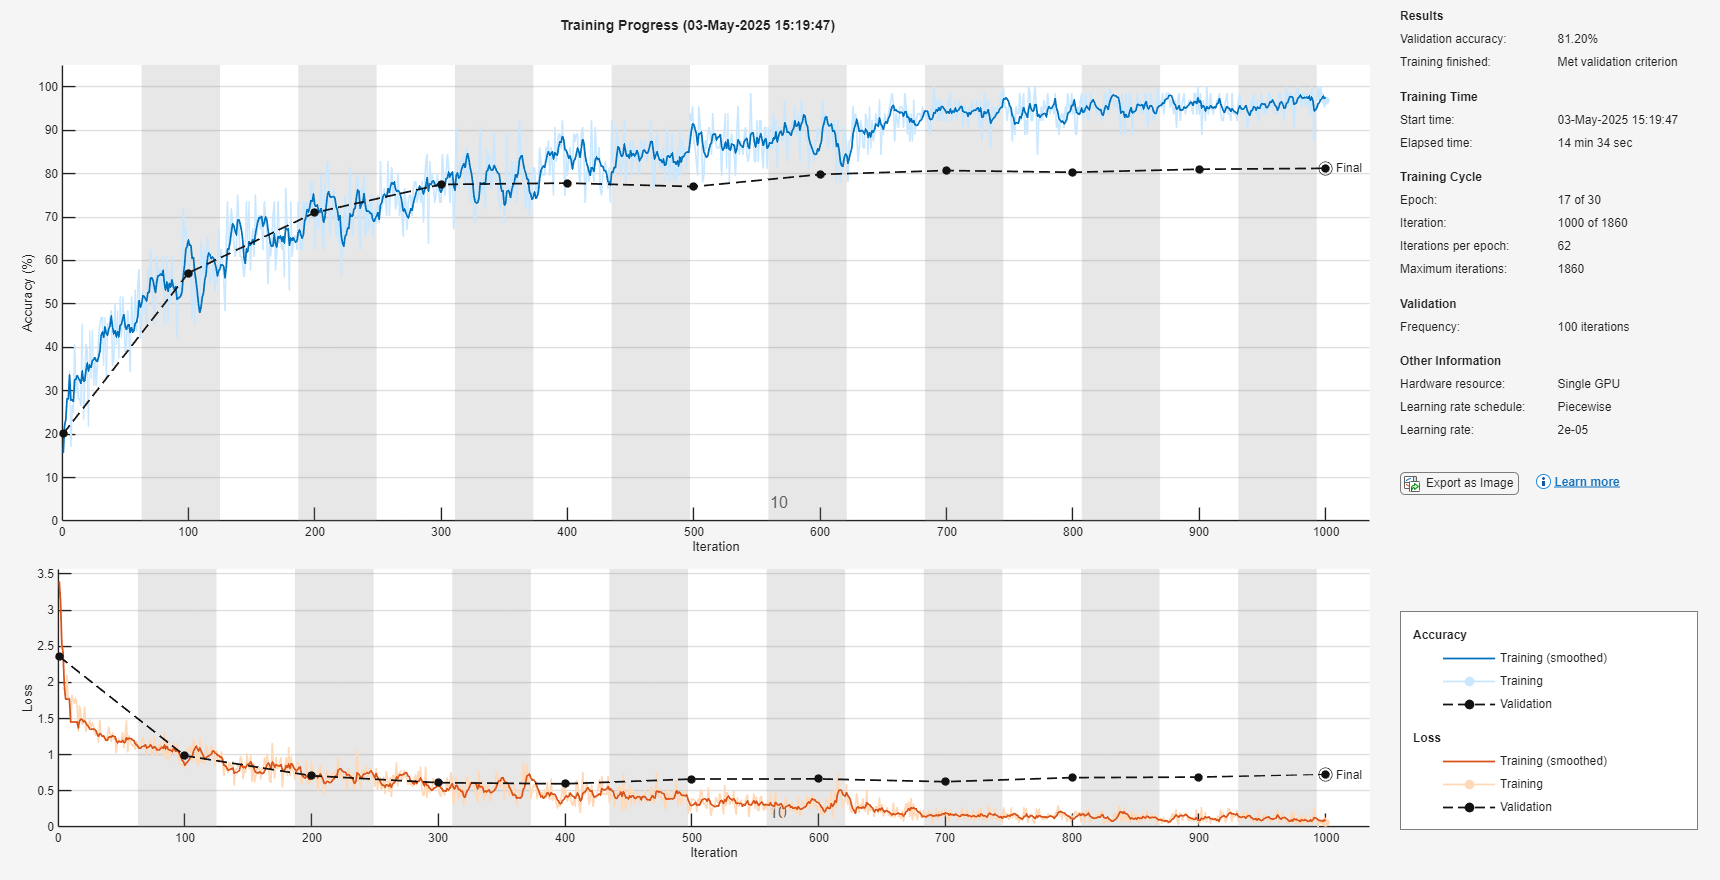

trainedNet = trainNetwork(augTrain, lgraph, options);

disp("   Training complete.");

   Training complete.


save('trainedHandGestureModel_AlexNet_Optimized.mat', 'trainedNet');

%% Step 8: Evaluate Performance
disp("8) Evaluating model...");

8) Evaluating model...



function score = TTAclassify(net, img, inputSize)
  variants = {img, fliplr(img), imrotate(img,15,'crop'), imcrop(img,[1 1 inputSize])};
  S = zeros([numel(net.Layers(end).Classes), numel(variants)]);
  for k = 1:numel(variants)
    v = imresize(variants{k}, inputSize);
    if size(v,3) == 1, v = cat(3,v,v,v); end
    [~, s] = classify(net, v);
    S(:,k) = s;
  end
  score = mean(S,2);
end

scores = zeros(numel(valImgs.Files), numClasses);
for i = 1:numel(valImgs.Files)
  I = imread(valImgs.Files{i});
  I = imresize(I, inputSize(1:2));
  scores(i,:) = TTAclassify(trainedNet, I, inputSize(1:2));
end

[~,idx] = max(scores,[],2);
predLabels = classNames(idx);
trueLabels = valImgs.Labels;

% Accuracy
acc = mean(predLabels == trueLabels);
fprintf("   Validation Accuracy: %.2f%%\n", acc*100);

   Validation Accuracy: 81.50%


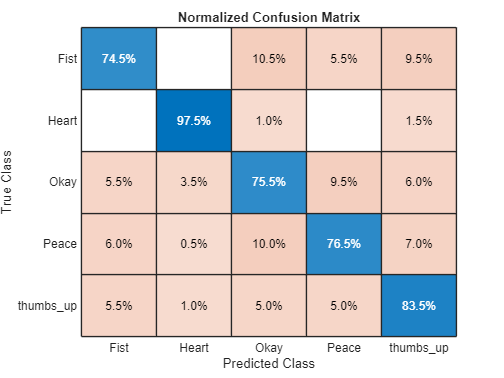


% Confusion Matrix
figure('Name','Confusion Matrix','NumberTitle','off');
confusionchart(trueLabels, predLabels, 'Normalization','row-normalized');
title('Normalized Confusion Matrix');


% Precision / Recall / F1
confMat = confusionmat(trueLabels, predLabels);
prec = diag(confMat)./sum(confMat,2);
rec  = diag(confMat)./sum(confMat,1)';
f1   = 2*(prec.*rec)./(prec+rec);
disp("   Per-Class Metrics:");

   Per-Class Metrics:


disp(table(classNames, prec, rec, f1, ...
     'VariableNames', {'Class','Precision','Recall','F1'}));

      Class      Precision    Recall       F1   
    _________    _________    _______    _______

    Fist           0.745      0.81421    0.77807
    Heart          0.975      0.95122    0.96296
    Okay           0.755       0.7402    0.74752
    Peace          0.765      0.79275    0.77863
    thumbs_up      0.835      0.77674    0.80482



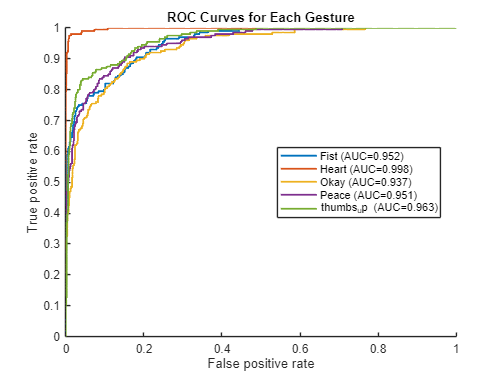


% ROC / AUC
figure('Name','ROC Curves','NumberTitle','off'); hold on;
auc = zeros(numClasses,1);
for c = 1:numClasses
  [X,Y,~,auc(c)] = perfcurve(trueLabels, scores(:,c), classNames(c));
  plot(X,Y,'LineWidth',1.5);
end
legend(string(classNames)+" (AUC="+string(round(auc,3))+")",'Location','best');
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curves for Each Gesture');


disp("Model saved as 'trainedHandGestureModel_AlexNet_Optimized.mat'");

Model saved as 'trainedHandGestureModel_AlexNet_Optimized.mat'


disp("All done!");

All done!
